syms a1 a2 b1 c1 d q

I  = [[q 0]; [0 q]];
A = [[a1 a2];[0 0.5]];
B = [b1 ; 1];
C = [1 c1];
D = d;

simplify(C*inv(q-A)*B + D)

$$ans = -\frac{b_{1}-2\,a_{2}+2\,q+2\,a_{1}\,c_{1}-a_{1}\,d-2\,b_{1}\,q-2\,c_{1}\,q+d\,q+2\,a_{1}\,d\,q-2\,a_{2}\,d\,q+2\,b_{1}\,c_{1}\,q}{a_{1}-q-2\,a_{1}\,q+2\,a_{2}\,q}$$

iodata = load("ch5230_21_Q3ssdata.mat");
mean(iodata.yk)

ans = -10.5464

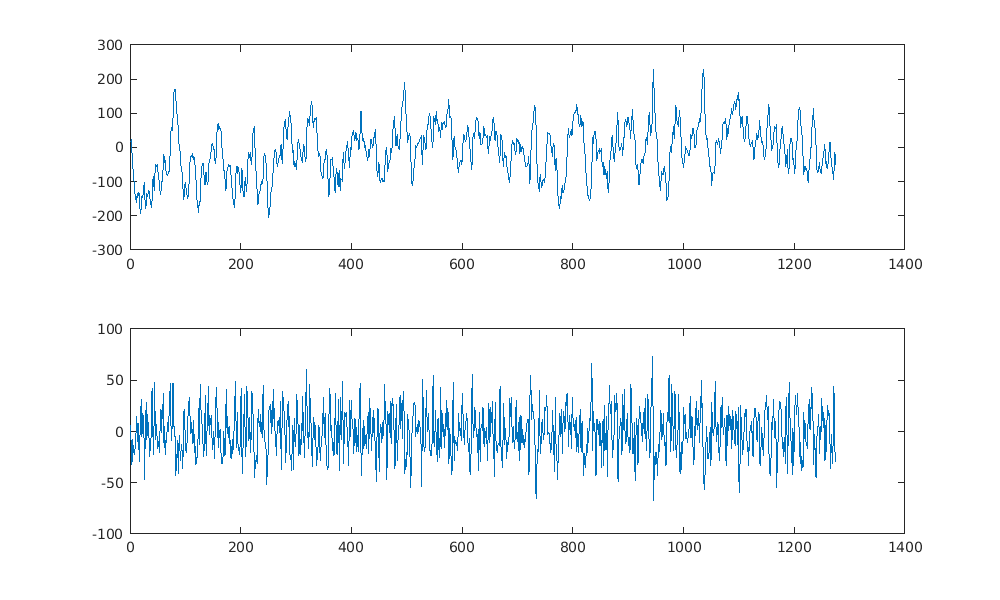

figure;set(gcf,'position',[10,10,1000,600]);

subplot(2,1,1)
plot(iodata.yk)

subplot(2,1,2)
% plot(iodata.yk(3:end) - 2*iodata.yk(2:end-1) + iodata.yk(1:end-2))
plot(iodata.yk(2:end) - iodata.yk(1:end-1))


% Train-Test split:
% dataset = iddata(iodata.yk(2:end) - iodata.yk(1:end-1), iodata.uk(2:end), 1);
dataset = iddata(iodata.yk, iodata.uk, 1);
datatrain = dataset;
[Ztrain ,Tr] = detrend(datatrain, 0);

% 99 % significance levels
clim = 2.58/sqrt(length(Ztrain.y));

mod_oe = arx(Ztrain ,[2 1 1]);
present(mod_oe);

                                                                              
mod_oe =                                                                      
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                           
  A(z) = 1 - 1.393 (+/- 0.0238) z^-1 + 0.4711 (+/- 0.02352) z^-2              
                                                                              
  B(z) = 2.801 (+/- 0.261) z^-1                                               
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=2   nb=1   nk=1                                    
   Number of free coefficients: 3                                             
   Use "polydata", "getpvec", "getcov" for parameter

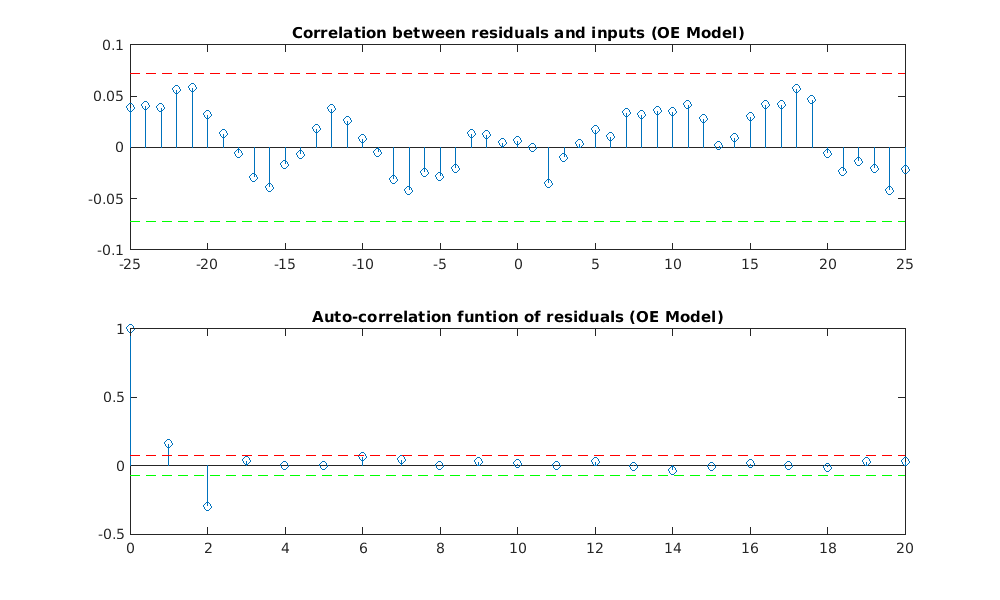

yhat_oe = predict(mod_oe , Ztrain );       % Predictions on training data
err_oe = pe(mod_oe , Ztrain );             % Compute one-step ahead prediction errors

% Residual analysis:
cross_corr_oe = xcov(err_oe.y, Ztrain.u,25,'coeff');
acf_oe = xcov(err_oe.y,20,'coeff');

% Plot
figure;set(gcf,'position',[10,10,1000,600]);

subplot(211); stem( -25:25 , cross_corr_oe ); hold on
plot([ -25 25] ,[1 1]* clim ,'r--' ,[-25 25] ,[ -1 -1]*clim ,'g--')
title('Correlation between residuals and inputs (OE Model)')

subplot(212); stem((0:20) ,acf_oe (21:end)); hold on
plot([0 20] ,[1 1]* clim ,'r--' ,[0 20] ,[ -1 -1]*clim ,'g--')
title('Auto-correlation funtion of residuals (OE Model)')